# CAD design of the CNN-like structure

**Description:** This code evaluates the coordinates for the upper lines and lower lines for each pipe. As represented on Fig. 1, we define each pipe coordinates with points. The meaning for 

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_w_100um_rectangular_tetrazine');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_w_100um_rectangular_tetrazine


#### Parameters

%call to the parameters file
Parameters

Q_uL_m = 2

p0 = 300

mu = 9.9792e-04

D_coeff = 4.9000e-10

## Reference coordinates

%this reference coordinates are coming from the original CAD desing. This
%two points reference refer to the pipe just after the mixer on the
%transmitter side. See Fig. 1.
P_u0=[-42.36063776 1.75826183]*1e-3;
P_b0=[-42.36063776 1.65926683]*1e-3;
%width for the mixer pipe
w_0=P_u0(2)-P_b0(2);

fprintf('P_u0\n')

P_u0


fprintf('%.8f', P_u0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_u0(2)*1e3);   % fixed-point with 15 decimals

1.75826183


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_b0(2)*1e3);   % fixed-point with 15 decimals

1.65926683

## Pipe 2

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_2_w_vs_varphi.mat'))

idx=find(w_vs_varphi_pipe_2~=0);
varphi_2=varphi_vec(idx(1));
w_2=w_vs_varphi_pipe_2(idx(1))

w_2 = 1.5802e-04


%length of the pipe
L_2=L_1/sin((pi-varphi_2)/2);
%heigth of the pipe
alpha=asin(L_1/L_2);
h_2=sqrt((L_2/2)^2-(L_1/2)^2);

P_u21=P_u0+[L_1/2 h_2];
fprintf('P_u21\n')

P_u21


fprintf('%.8f', P_u21(1)*1e3);   % fixed-point with 15 decimals

-31.86063776

fprintf('%.8f', P_u21(2)*1e3);   % fixed-point with 15 decimals

12.20488629


P_b21=P_u21+[w_2/h_2*L_2/2 0];
fprintf('P_b21\n')

P_b21


fprintf('%.8f', P_b21(1)*1e3);   % fixed-point with 15 decimals

-31.63658900

fprintf('%.8f', P_b21(2)*1e3);   % fixed-point with 15 decimals

12.20488629


P_b22=P_u21+[0 -w_2/sin(alpha)];
fprintf('P_b22\n')

P_b22


fprintf('%.8f', P_b22(1)*1e3);   % fixed-point with 15 decimals

-31.86063776

fprintf('%.8f', P_b22(2)*1e3);   % fixed-point with 15 decimals

11.98197646


P_u23=P_u21+[L_1_prima 0];

Unrecognized function or variable 'L_1_prima'.

fprintf('P_u23\n')
fprintf('%.8f', P_u23(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u23(2)*1e3);   % fixed-point with 15 decimals

P_b23=P_u21+[L_1_prima-w_2/h_2*L_2/2 0];
fprintf('P_b23\n')
fprintf('%.8f', P_b23(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b23(2)*1e3);   % fixed-point with 15 decimals


## Pipe 1

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_1_w_vs_l.mat'))

idx=find(w_vs_l_pipe_1~=0);

%selecting the shortest distance
L_1=l_vec(idx(1))
w_1=w_vs_l_pipe_1(idx(1))


P_b11=P_b0-[0 w_1/2];
fprintf('P_b11\n')
fprintf('%.8f', P_b11(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b11(2)*1e3);   % fixed-point with 15 decimals

P_b12=P_b11+[L_1 0];
fprintf('P_b12\n')
fprintf('%.8f', P_b12(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b12(2)*1e3);   % fixed-point with 15 decimals


## Pipe 3

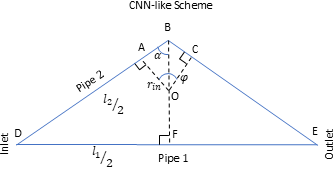

Figure 2: Reference angles within the pipe.

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_3_w_vs_varphi.mat'))

idx=find(w_vs_varphi_pipe_3~=0);
varphi_3=varphi_vec(idx(1));
w_3=w_vs_varphi_pipe_3(idx(1))

P_u31=P_u0+[0 w_1/2];
fprintf('P_u31\n')
fprintf('%.8f', P_u31(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u31(2)*1e3);   % fixed-point with 15 decimals

%length of the pipe
L_3=L_1/sin((pi-varphi_3)/2);
%heigth of the pipe
alpha=asin(L_1/L_3);
h_3=sqrt((L_3/2)^2-(L_1/2)^2);

P_u32=P_u31+[L_1/2 h_3];
fprintf('P_u32\n')
fprintf('%.8f', P_u32(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u32(2)*1e3);   % fixed-point with 15 decimals

P_u33=P_u31+[L_1 0];
fprintf('P_u33\n')
fprintf('%.8f', P_u33(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u33(2)*1e3);   % fixed-point with 15 decimals

P_b31=P_u31+[w_3/h_3*L_3/2 0];
fprintf('P_b31\n')
fprintf('%.8f', P_b31(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b31(2)*1e3);   % fixed-point with 15 decimals

P_b32=P_u32+[0 -w_3/sin(alpha)];
fprintf('P_b32\n')
fprintf('%.8f', P_b32(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b32(2)*1e3);   % fixed-point with 15 decimals

P_b33=P_u31+[L_1-w_3/h_3*L_3/2 0];
fprintf('P_b33\n')
fprintf('%.8f', P_b33(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b33(2)*1e3);   % fixed-point with 15 decimals


## Outlet

outlet_length=3e-3;
P_u11=P_u33+[outlet_length 0];
fprintf('P_u11\n')
fprintf('%.8f', P_u11(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u11(2)*1e3);   % fixed-point with 15 decimals

P_b13=P_b12+[outlet_length 0];
fprintf('P_b13\n')
fprintf('%.8f', P_b13(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b13(2)*1e3);   % fixed-point with 15 decimals

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  